trial_ind = 85;
figure;
disturbance_onset =  trajectory_struct(trial_ind).processed.disturbance_onset

%plot(trajectory_struct(trial_ind).spoutLH(disturbance_onset-450:disturbance_onset+150-1)*50)
%hold on
plot(trajectory_struct(trial_ind).spoutX(disturbance_onset-50:disturbance_onset+150-1))
%hold on
%plot(diff(trajectory_struct(trial_ind).spoutX(disturbance_onset-50:disturbance_onset+150-1)))
figure;
plot(trajectory_struct(trial_ind).spoutY(disturbance_onset-450:disturbance_onset+150-1))
%hold on
%plot(diff(trajectory_struct(trial_ind).spoutY(disturbance_onset-50:disturbance_onset+150-1)))
plot(trajectory_struct(trial_ind).noseX(disturbance_onset-450:disturbance_onset+150-1))
plot(trajectory_struct(trial_ind).noseY(disturbance_onset-450:disturbance_onset+150-1))


if strcmp(mouseID,'CB005')
    search_path = fullfile('S:\new_analysis_results\',mouseID, date_of_experiment,'trajectory_struct_020*');
elseif strcmp(mouseID, 'CB006')
    search_path = fullfile('S:\new_analysis_results\',mouseID, date_of_experiment,'trajectory_struct_01*');
end

file_to_load=dir(fullfile(search_path));

previous=load(fullfile(file_to_load.folder, file_to_load.name));

plot(previous.trajectory_struct(trial_ind).noseLH(disturbance_onset-450:disturbance_onset+150-1))


%%
org_spoutY = trajectory_struct(trial_ind).spoutY(disturbance_onset-450:disturbance_onset+150-1);
jumpcorrected_spoutY = org_spoutY;
diff_jumpcorrected_spoutY=diff(org_spoutY);
jump_indexes = find(abs(diff_jumpcorrected_spoutY) > 15)

jump_indexes =     12
    25
    29
    41
    50
    64
    80
   107
   113
   118


peri_perturb_JI = jump_indexes(find(jump_indexes > 450 & jump_indexes < 485))

peri_perturb_JI =    451
   456


post_perturb_JI = jump_indexes(find(jump_indexes >= 485))


post_perturb_JI =

  0×1 empty double column vector



pre_perturb_JI = jump_indexes(find(jump_indexes <= 450))

pre_perturb_JI =     12
    25
    29
    41
    50
    64
    80
   107
   113
   118


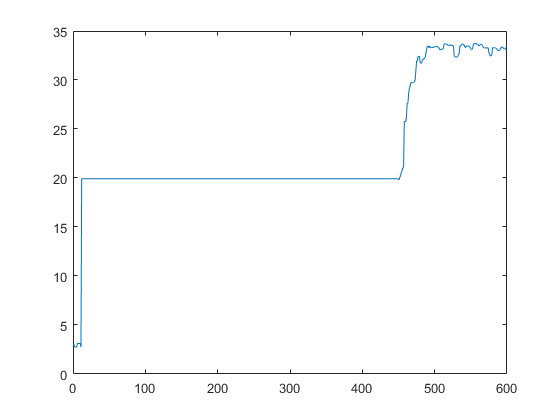


if abs(20-jumpcorrected_spoutY(pre_perturb_JI(1)+1)) < abs(20-jumpcorrected_spoutY(pre_perturb_JI(1)))
    
    jumpcorrected_spoutY(pre_perturb_JI(1):pre_perturb_JI(end)) = jumpcorrected_spoutY(pre_perturb_JI(1)+1);
else
    jumpcorrected_spoutY(pre_perturb_JI(1)+1:pre_perturb_JI(end)) = jumpcorrected_spoutY(pre_perturb_JI(1));
    
end

for i=1:length(post_perturb_JI)
    
    jumpcorrected_spoutY(post_perturb_JI(i)+1:end) = jumpcorrected_spoutY(post_perturb_JI(1));
    
end


if length(peri_perturb_JI) ==2
    
    num_of_points = peri_perturb_JI(2) - peri_perturb_JI(1);
    
    start_edge = jumpcorrected_spoutY(peri_perturb_JI(1));
    end_edge = jumpcorrected_spoutY(peri_perturb_JI(2)+1);
    increment = (end_edge - start_edge)/num_of_points;
    for j =1:num_of_points
        jumpcorrected_spoutY(peri_perturb_JI(1)+j) = jumpcorrected_spoutY(peri_perturb_JI(1)) + increment*j;
        
    end
end

if length(peri_perturb_JI) ==3
    
    num_of_points = peri_perturb_JI(3) - peri_perturb_JI(1);
    start_edge = jumpcorrected_spoutY(peri_perturb_JI(1));
    end_edge = jumpcorrected_spoutY(peri_perturb_JI(3)+1)
    increment = (end_edge - start_edge)/num_of_points;
    for j =1:num_of_points
        jumpcorrected_spoutY(peri_perturb_JI(1)+j) = jumpcorrected_spoutY(peri_perturb_JI(1)) + increment*j;
        
    end
end

figure;
plot(jumpcorrected_spoutY)

%%
% retrieve noseDist
relative_noseX=trajectory_struct(trial_ind).noseX(disturbance_onset-450:disturbance_onset+150-1) - trajectory_struct(trial_ind).spoutX(disturbance_onset-450:disturbance_onset+150-1);
relative_noseY=trajectory_struct(trial_ind).noseY(disturbance_onset-450:disturbance_onset+150-1) - jumpcorrected_spoutY;
relative_nose = sqrt((relative_noseX.^2)+(relative_noseY.^2));
noseDist=relative_nose
figure;
plot(relative_noseX)